clc
clear
alpha_simulazione = 0;
t_end = 20;
Ts = 1/100;
theta_iniziale = 5 *pi/180;
load("K.mat")
K =[-1.0000 ,  -4.2629, -463.4547, -216.7364];


control_on = 0;
simOut = sim('VAB_non_linear.slx');
completeState = simOut.completeState;
tout = simOut.tout;
phi = simOut.completeState(:,1);
phi_p = simOut.completeState(:,2);
theta = simOut.completeState(:,3);
theta_p = simOut.completeState(:,4);
figure
plot(tout, theta)
xlabel('Time [s]')
ylabel('Angle [°]')
%yline(180,'--','180°','linewidth',2);
title('Simulazione in anello aperto')
hold on
plot(tout,theta_p);
legend('Angular position','Angular velocity')

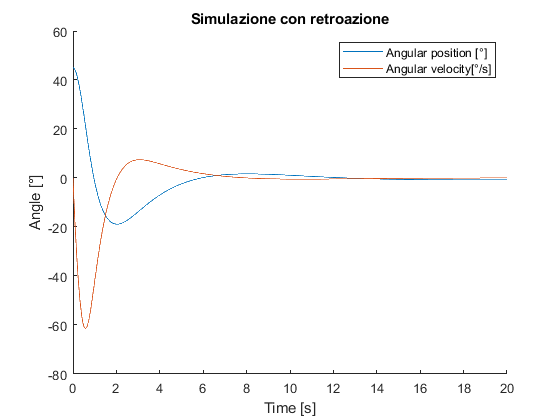

control_on = 1;
simOut = sim('VAB_non_linear.slx');
completeState = simOut.completeState;
tout = simOut.tout;
phi = 180/pi* simOut.completeState(:,1);
phi_p = 180/pi* simOut.completeState(:,2);
theta = 180/pi*simOut.completeState(:,3);
theta_p = 180/pi* simOut.completeState(:,4);
torque = simOut.TorqueFeeded;
figure
hold on
plot(tout, theta)
xlabel('Time [s]')
ylabel('Angle [°]')
title('Simulazione con retroazione')
hold on
plot(tout,theta_p);
legend('Angular position [°]','Angular velocity[°/s]')
hold off

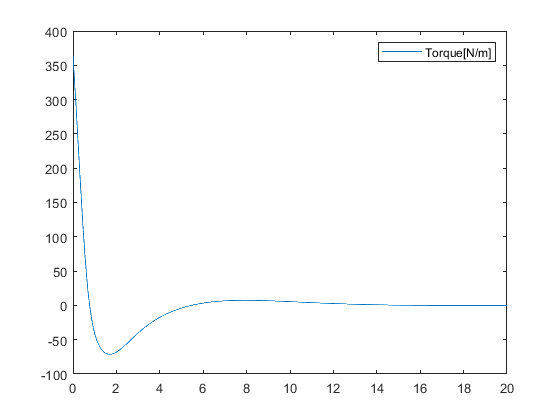

plot(tout,torque)
legend('Torque[N/m]')

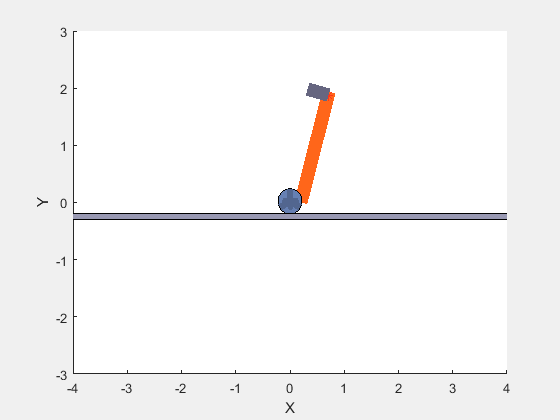

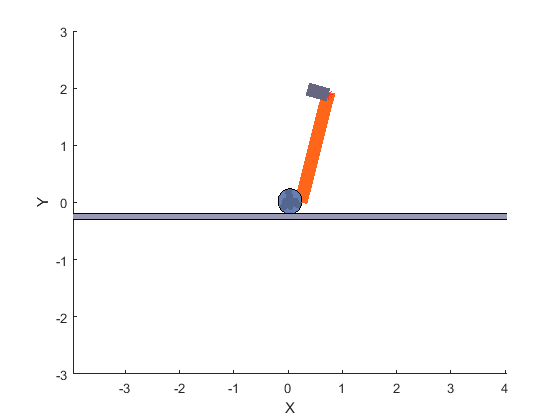

set(gcf,'Visible','on');
    for i = 1:length(tout)
         call_plot(completeState(i,:));
         pause(1/20)
    end

close all;
    
   